# Machine Learning with MATLAB

Industrial AI & Automation  

# Classification with LDA, QDA

## Data Acquisition

### Dataset 1:  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

clear

%% Train
load("../3_MachingLearning/CWRU_Datas/example_train.mat");

feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor

X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));

Y = class_cwru_train;           % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);


%% Test
load("../3_MachingLearning/CWRU_Datas/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;          

Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);

#### Plot Test Data

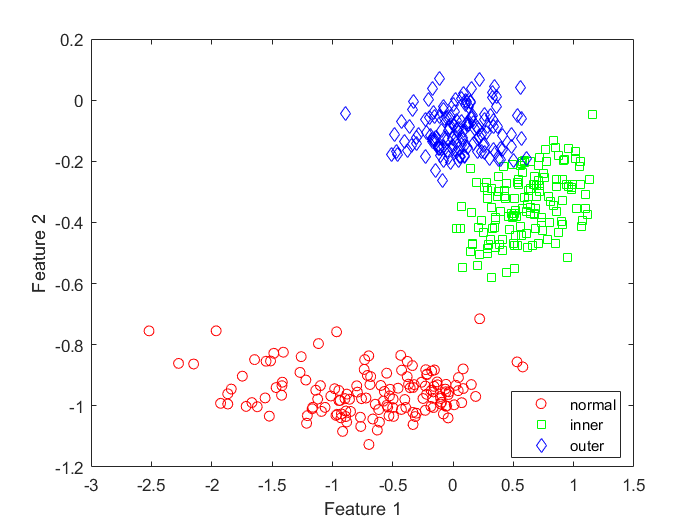

f = figure;
gscatter(X(:, 1), X(:, 2), Y,'rgb','osd');
xlabel('Feature 1')
ylabel('Feature 2') 

## Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)

% k-fold
cv = cvpartition(Y,'KFold',10)  

cv = K-fold cross validation partition
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

# LDA Classification 

fitdiscr()

### Classify with LDA **(Use all Data to train)**

% LDA model
lda = fitcdiscr(X,Y, 'DiscrimType', 'linear');

### **Anlayze **

**Resubstitution error**:  misclassification error  on the training set.

% percentage of observations that were incorrectly predicted by some classification model.
ldaResubErr = resubLoss(lda)

ldaResubErr = 0.0116

**Confusion matrix** on whole Data set

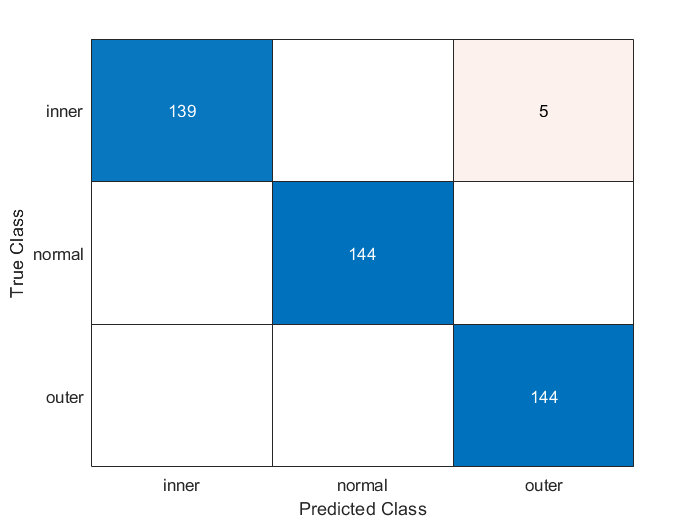

ldaClass = resubPredict(lda);

% training data의 결과
figure

% input parameter : true class, predicted class
ldaResubCM = confusionchart(Y,ldaClass);

**Misclassification Plot**

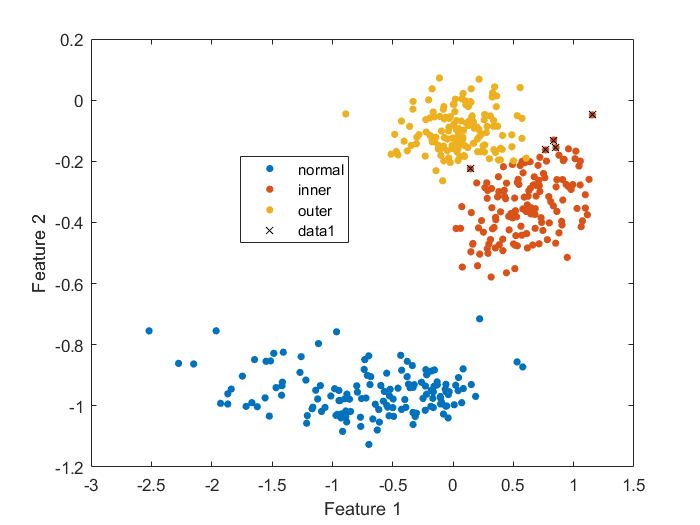

% 예측한 라벨, 실제 라벨을 비교하여 다른 것만 보내준다.
% outer와 inner의 근방에 존재하는 데이터들 --> 추출
bad = ~strcmp(ldaClass,Y);

figure
gscatter(X(:,1),X(:,2),Y)
hold on;
plot(X(bad,1), X(bad,2), 'kx');
hold off;
xlabel('Feature 1')
ylabel('Feature 2')

**Visualize Separation regions **

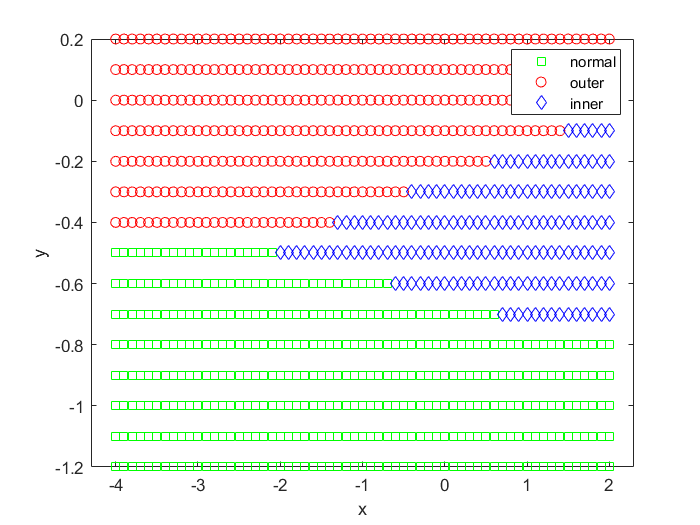

[x,y] = meshgrid(-4:.1:2,-1.2:.1:0.2);
x = x(:);
y = y(:);
j = classify([x y],X,Y);            % classify() for LDA / LQA. use predict(_) otherwise
gscatter(x,y,j,'grb','sod')

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

### Classify with LDA (using CV-TrainSet)

% Fit LDA classifier on the entire training data
% 10개의 폴드로 나눈 데이터를 사용하여 LDA 분류기를 학습 | CVPartition 옵션을 사용하여 교차 검증 수행

cvLDA = crossval(lda, 'CVPartition', cv);

ldaCVErr = kfoldLoss(cvLDA)                     % loss on validation fold

ldaCVErr = 0.0139

cp = cvpartition(N, "HoldOut", 0.3);

% train인 경우 1
trainInds = training(cp);
% sample인 경우 1
sampleInds = test(cp);

trainingData  = X(trainInds, 1:2);
sampleData    = X(sampleInds, 1:2);
trainingLabel = Y(trainInds);
sampleLabel   = Y(sampleInds);

% classify로 predict
[class, err, posterior, logp, coeff] = classify(sampleData,trainingData,trainingLabel);
disp('validation error')

validation error


err

err = 0.0063

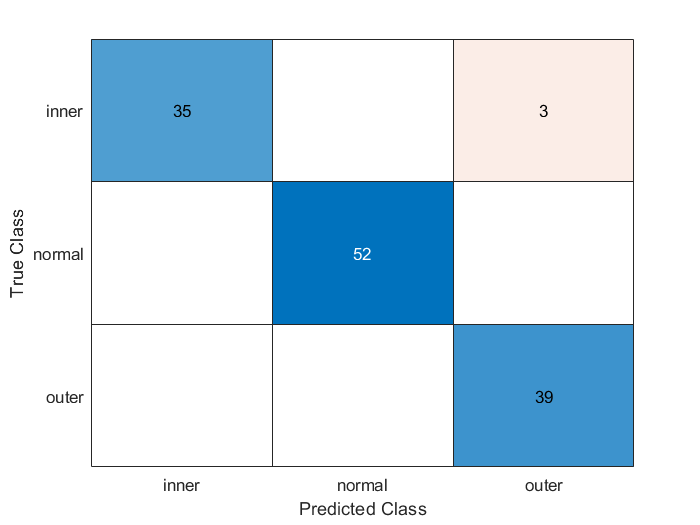

% Validate with CV-Test Set 
cm = confusionchart(sampleLabel,class);

### Predict test data

Predict the classification of test data (Xtest)

predictClass = predict(lda, Xtest);

**Calculate the loss  of Test**

L = loss(lda, Xtest, Ytest);

**Plot  Confusion matrix of Test data**

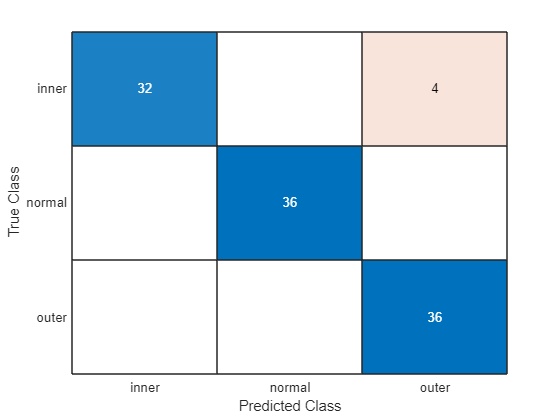

predictChart = confusionchart(Ytest, predictClass);

**Plot  Test Results**

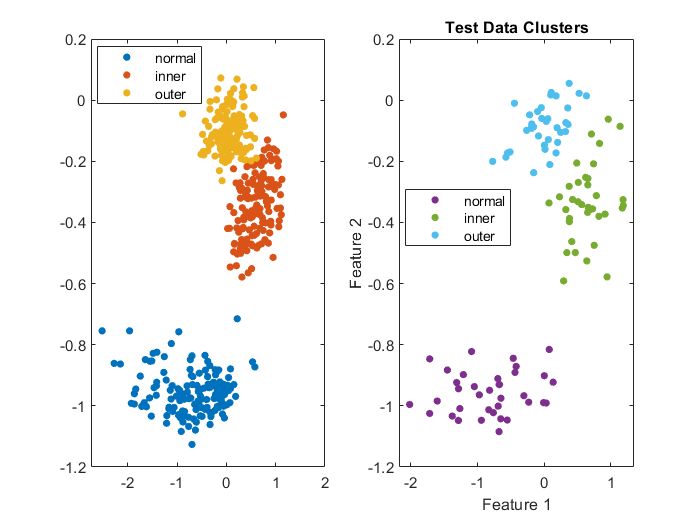

color = lines(6);                                       % Generate color values
figure

subplot(1,2,1)
gscatter(X(:,1),X(:,2),Y, color(1:3,:))

subplot(1,2,2)
gscatter(Xtest(:,1), Xtest(:,2), Ytest, color(4:6,:))
title('Test Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2') 

# QDA Classification 

fitdiscr()

### Fit QDA

% LQA model
qda = fitcdiscr(X, Y, 'discrimType', 'quadratic');

### **Anlayze (All Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

% Classify the training set
lqaClass = resubPredict(qda);

lqaResubErr = resubLoss(qda);

**Confusion matrix** on the training set

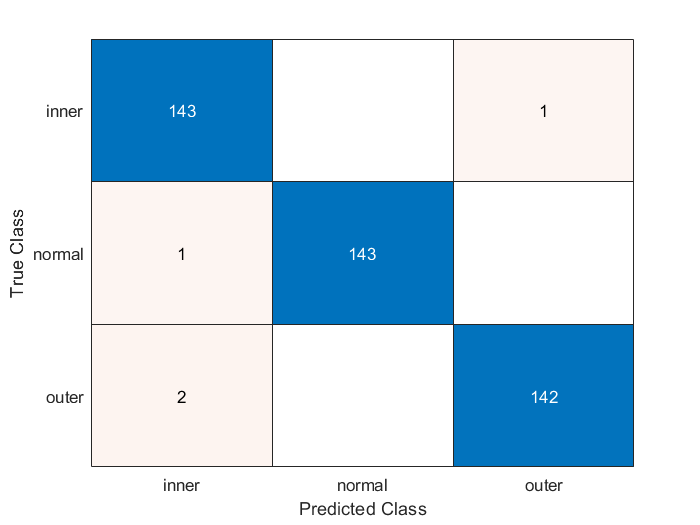

figure

% Create a confusion matrix for the LQA model on the test set
lqaResubCM = confusionchart(Y, lqaClass);

**Misclassification Plot**

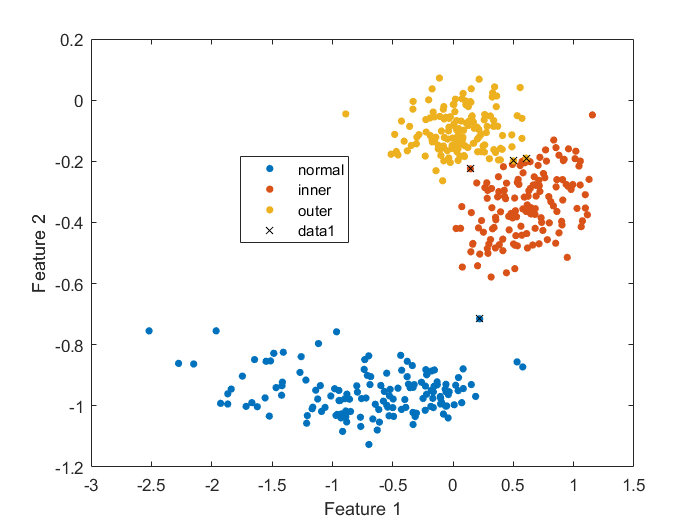

bad = ~strcmp(lqaClass, Y);
figure;
gscatter(X(:,1),X(:,2),Y);
hold on;
plot(X(bad,1), X(bad,2), 'kx');
hold off;
xlabel('Feature 1');
ylabel('Feature 2');

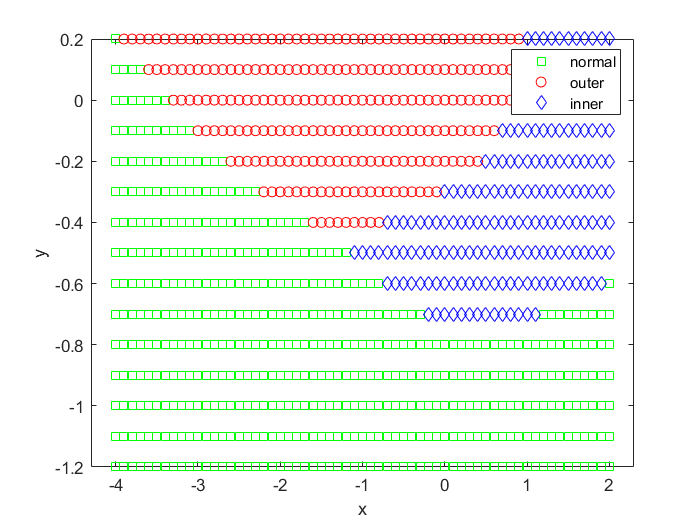

% Visualize Separation regions 
[x, y] = meshgrid(-4:.1:2, -1.2:.1:0.2);
x = x(:);
y = y(:);
j = predict(qda, [x y]);
gscatter(x, y, j, 'grb', 'sod');

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

cvQDA = crossval(qda, 'CVPartition', cv);
quaCVErr = kfoldLoss(cvQDA)

quaCVErr = 0.0093

### Predict test data

Predict the classification of test data

predictClass_qda = predict(qda,Xtest)

predictClass_qda = 108×1 cell array
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


**Calculate the loss  of Test**

L=loss(qda, Xtest, Ytest);

**Plot  Confusion matrix of Test data**

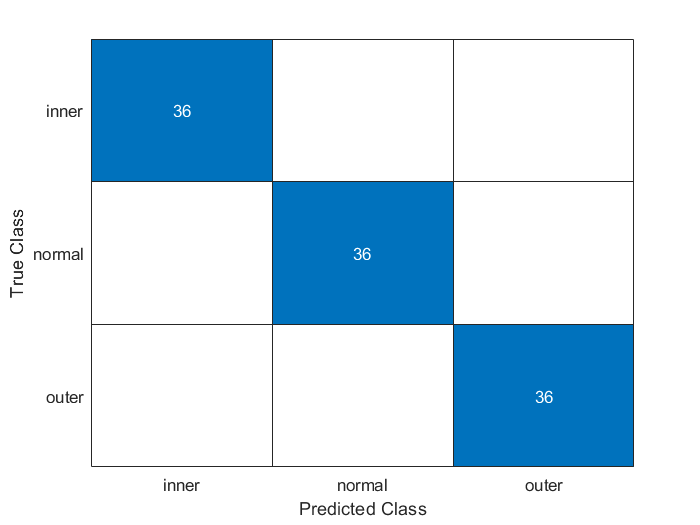

resubCM = confusionchart(Ytest,predictClass_qda);

# Exercise

## Exercise 1: 

Now, Select any 3 features and repeat the process. 

- 3개의 feature에 대해서 해보기

**Features**

clear

% Example
load("../3_MachingLearning/CWRU_Datas/example_train.mat");
X(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
X(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
X(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

Y = class_cwru_train;                                 % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);


%% Test
load("../3_MachingLearning/CWRU_Datas/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, "kv"));
Xtest(:, 2) = table2array(glob_all_test(:, "mf"));
Xtest(:, 3) = table2array(glob_all_test(:, "cf"));

Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);

tblTest = table(Xtest(:, 1),Xtest(:, 2),Ytest);

Plot the test and train results in 3D graph.

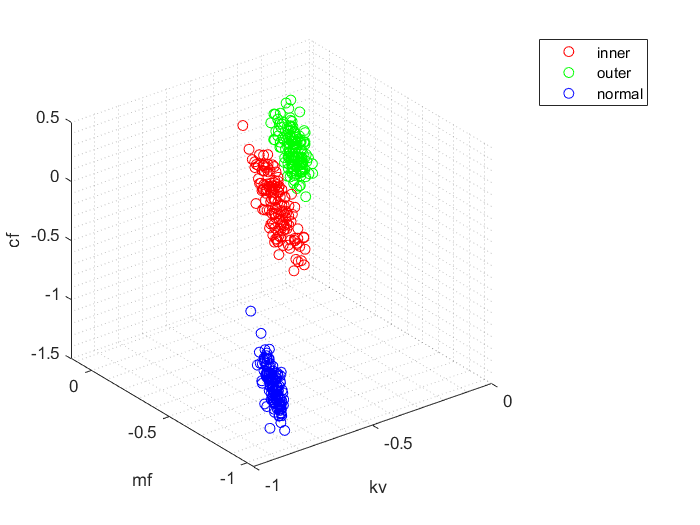

yCate = categorical(Y);
idx_inner = yCate == 'inner';
idx_outer = yCate == 'outer';
idx_normal = yCate == 'normal';

figure
plot3(X(idx_inner,1),X(idx_inner,2),X(idx_inner,3),'ro')
hold on
plot3(X(idx_outer,1),X(idx_outer,2),X(idx_outer,3),'go')
plot3(X(idx_normal,1),X(idx_normal,2),X(idx_normal,3),'bo') 
grid minor
xlabel('kv')
ylabel('mf')
zlabel('cf')
legend('inner','outer','normal')
hold off

## Exercise 2 

Compare performance of Logistic Regression vs LDA vs LQA for CWRU dataset

lda = fitcdiscr(X,Y);
ldaResubErr = resubLoss(lda)

ldaResubErr = 0

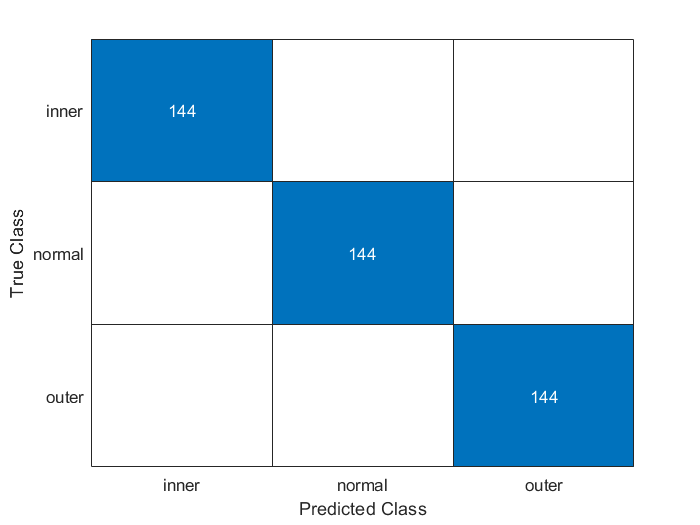

ldaClass = resubPredict(lda);

figure
ldaResubCM = confusionchart(Y,ldaClass);

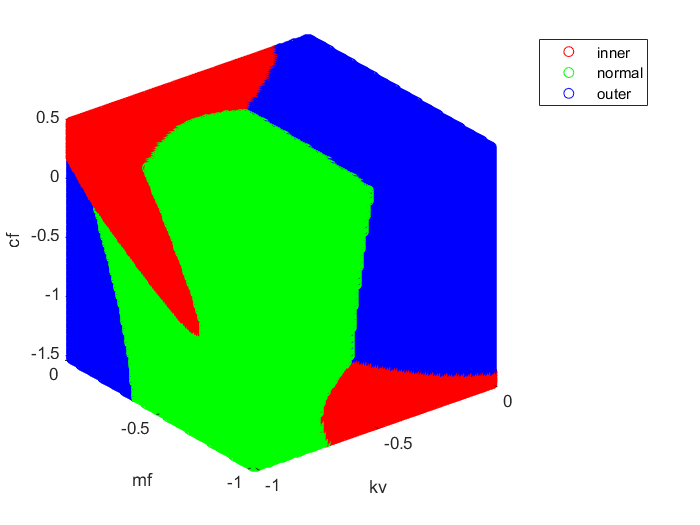

figure()
badLDA = ~strcmp(ldaClass,Y);

figure
plot3(X(badLDA,1), X(badLDA,2), X(badLDA,3), 'kx');

grid minor;  xlabel('kv');  ylabel('mf');   zlabel('cf');
% Visualize Separation regions 
[x,y,z] = meshgrid(-1:0.01:0 , -1:0.01:0 , -1.5:.01: 0.5);

x = x(:);
y = y(:);
z = z(:);

j = classify([x y z],X , Y, 'quadratic');         

group = unique(j); 
color = ['r';'g';'b'];

for k = 1:length(group)
      
      ind = strcmp(j,group(k));

      plot3(x(ind),y(ind),z(ind), 'o', 'color', color(k,:))
      hold on
end
legend(group);
xlabel('kv');   ylabel('mf');   zlabel('cf');
grid minor

qda = fitcdiscr(X, Y, 'DiscrimType', 'quadratic');
qdaResubErr = resubLoss(qda)

qdaResubErr = 0

qdaClass = resubPredict(qda);

figure
qdaResubCM = confusionchart(Y, qdaClass);

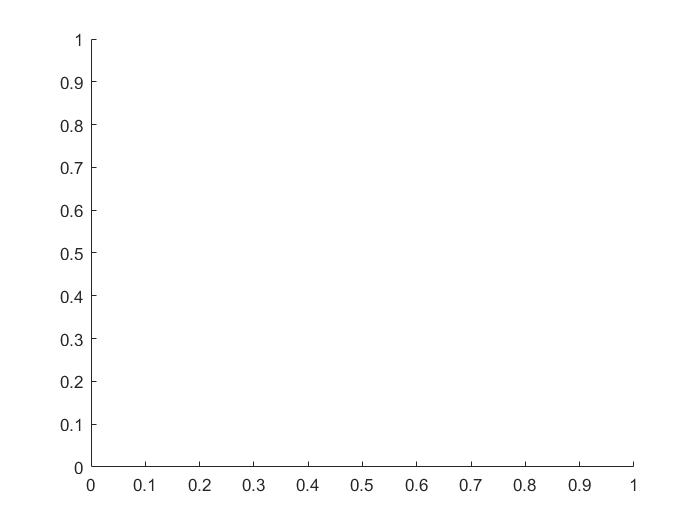

figure()
bad_qda = ~strcmp(qdaClass, Y);
hold on;

plot3(X(bad_qda,1), X(bad_qda,2), X(bad_qda,3), 'kx');
hold off;

## Performance analysis

Compare performance of Logistic Regression / LDA / LQA for CWRU dataset

- Linear regression and logistic regression techniques are appropriate for classifying data with two features in data including bearing data I classified. However, for classification involving three features, other techniques like LDA and QDA are more suitable. LDA assumes normally distributed data and a class-specific mean vector, with a common covariance matrix. Conversely, QDA assumes each class to have its own covariance matrix.

- Compared to QDA, LDA is less flexible because it requires the estimation of fewer parameters. This makes LDA useful when the training dataset has only a few observations and we want to reduce variance. However, when the K classes have significantly different covariance matrices, LDA is prone to high bias, and QDA might be a better choice.

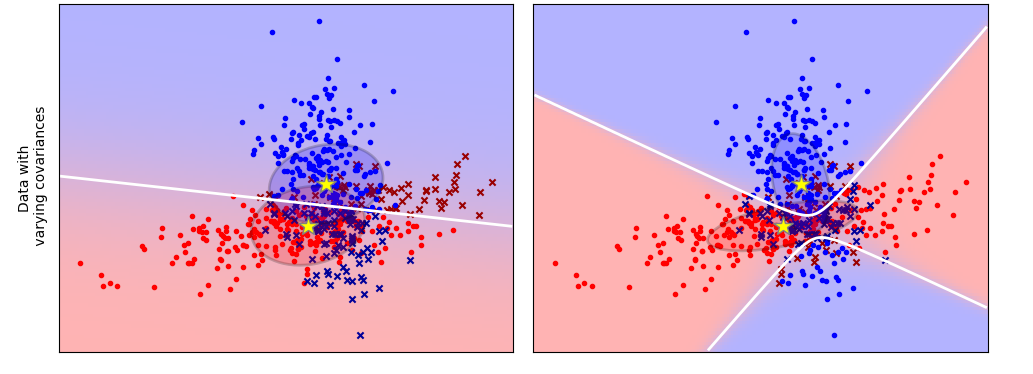

- Furthermore, in the exercise performed on the data involving three classification features (kf, mf, cf), all three classes (Inner, Outer, Normal) were well distinguished without any disparate data. Consequently, both LDA and QDA resulted in a loss of 0, making it difficult to compare their performances.